%The Below code does the following:
% 1. Generate data for given problem (9)
% 2. adjusts some step change.
% 3. Validate the for another step change.
% 
% 
% In the code below, We have fitted for a step change at some time 't_change' for a step change value of: 0.0202;
% And then we have fitted a FOPTD model using above data; obtaining the values of Kp; Tau; and time Delay;
% At last, we have predicted for a step change at t_change = 6000 and for step change value: 0.0102;
% The code works fine and can be fine-tuned and more beautified as well as complexity can be added.
%
%
%
% We have done all of the above for 1 parameter: that is : Biomass (X);


%Now starting with the code.% Define initial conditions and time span
y0 = [8; 8; 19.14];     % Initial conditions: y1(0) = 1, y2(0) = 2, y3(0) = 3
tspan = linspace(0, 10000, 10000);     % Time span for the solution


mu_m = 0.48;  % Maximum specific growth rate
P_m = 50;    % Maximum product concentration
K_m = 1.2;     % Michaelis-Menten constant
K_i = 22;   % Inhibition constant
S_f = 20 %g/L

S_f = 20

Y_x_s = 0.4 %g/g

Y_x_s = 0.4000

alpha = 2.2 %^^

alpha = 2.2000

beta = 0.2 %h^-1

beta = 0.2000

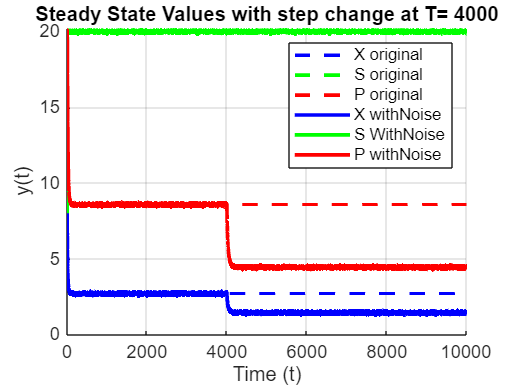



D = 0.202;
mu = @(S, P) (mu_m * (1 - P/P_m) .* S) ./ (K_m + S + (S.^2) / K_i);
%^^^^Mu (S, P and others is defined; and the default values of others is
%also given above it, so this reduces to a mu of only S and P as its
%independent variables. S-> y2, P->y3


soe = @(t, y) [-D* y(1) + mu(y(2), y(3))*y(1);
                D*(S_f-y(2))*(1/Y_x_s)*mu(y(2), y(3))*y(1);
               -D*y(3) + (alpha*mu(y(2), y(3)) + beta)*y(1)]; %y is a vector which contains 1st element as X, second as S, and third as P:


% Solve the system without step changes
[t_original, y_original] = ode45(soe, tspan, y0);

%Defining Step change algorithmically:

D = @(t) 0.202 + 0.0202*(t>= 4000); % + 0.0302*(t>4000 & t<=6000) + 0.0101*(t>6000 &t<8000); 
% Define the system of differential equations with step changes
dydt_step_change = @(t, y) [-D(t)* y(1) + mu(y(2), y(3))*y(1);
                D(t)*(S_f-y(2))*(1/Y_x_s)*mu(y(2), y(3))*y(1);
               -D(t)*y(3) + (alpha*mu(y(2), y(3)) + beta)*y(1)];
%Here, I have commented out another method in order to depict the step
%change variables. I would incorporate that later, if need be.


% Solve the system with step changes
[t_step, y_step] = ode45(dydt_step_change, tspan, y0);

% Add noise to the step-changed solution (random noise)
noise_amplitude = 0.05;  % Adjust this value for noise intensity
y_step_noisy = y_step+ noise_amplitude * randn(size(y_step));
%Commented out the noise.



% Plot the solutions

figure;
hold on;

% Plot the original solution (before step changes, dashed lines)
plot(t_original, y_original(:, 1), 'b--', 'LineWidth', 2, 'DisplayName', 'X original');
plot(t_original, y_original(:, 2), 'g--', 'LineWidth', 2, 'DisplayName', 'S original');
plot(t_original, y_original(:, 3), 'r--', 'LineWidth', 2, 'DisplayName', 'P original');

% Plot the noisy step-changed solution (solid lines with noise)
plot(t_step, y_step_noisy(:, 1), 'b-', 'LineWidth', 2, 'DisplayName', 'X withNoise');
plot(t_step, y_step_noisy(:, 2), 'g-', 'LineWidth', 2, 'DisplayName', 'S WithNoise');
plot(t_step, y_step_noisy(:, 3), 'r-', 'LineWidth', 2, 'DisplayName', 'P withNoise');

% Add labels, title, and legend
xlabel('Time (t)');
ylabel('y(t)');
title('Steady State Values with step change at T= 4000');
legend('show');
grid on;
hold off;

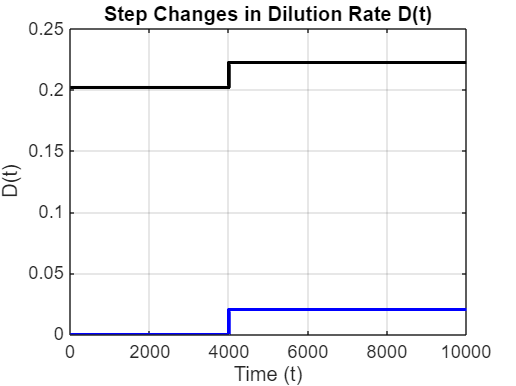


%Now, I have successfully done the following:
%Successfully generated the data and the plot.> Added the noise along with
%some step changes.

%Now, I want to develop FOPTD model; 
%How do I do that?

t_change=4000;
D = @(t) 0.202 + 0.0202*(t>= t_change); %+ 0.0302*(t>4000 & t<=6000) + 0.0101*(t>6000 & t<8000); 

% Plot D(t) over time
t_D = linspace(0, 10000, 10000);  % Time span for D(t)
D_values = D(t_D);  % Evaluate D(t)
D_values_norm = D_values - D(0);
figure; % Create a new figure
plot(t_D, D_values, 'k-', 'LineWidth', 2); % Plot D(t)
hold on;
plot(t_D, D_values_norm, 'b-', 'LineWidth', 2);
xlabel('Time (t)');
ylabel('D(t)');
title('Step Changes in Dilution Rate D(t)');
grid on;

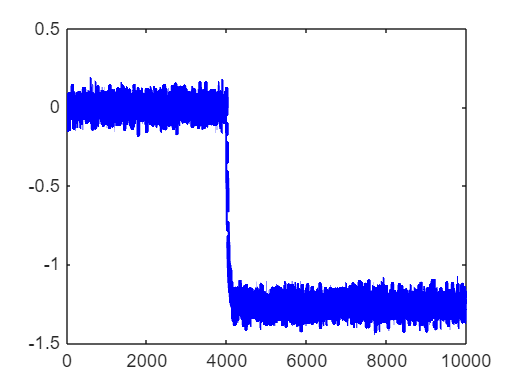


figure;
plot(t_step, y_step_noisy(:, 1)-y_original(:, 1), 'b-', 'LineWidth', 2, 'DisplayName', 'X withNoise');

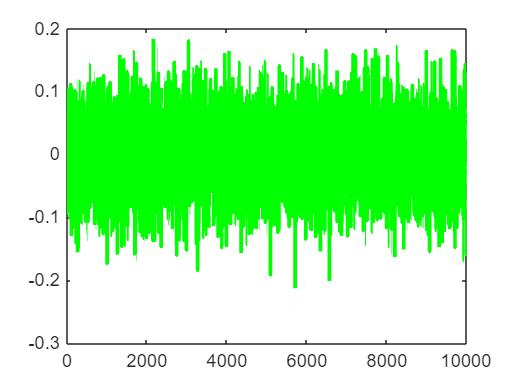

plot(t_step, y_step_noisy(:, 2)-y_original(:, 2), 'g-', 'LineWidth', 2, 'DisplayName', 'S WithNoise');

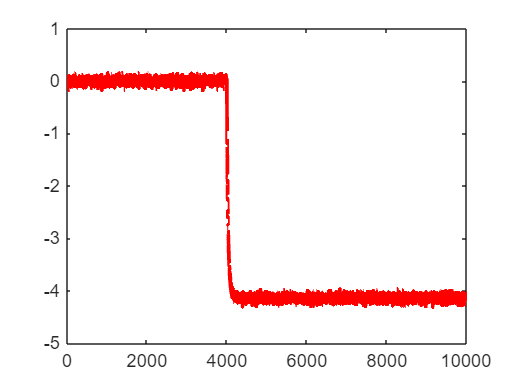

plot(t_step, y_step_noisy(:, 3)-y_original(:, 3), 'r-', 'LineWidth', 2, 'DisplayName', 'P withNoise');

norm_y1 = y_step_noisy(:, 1)-y_original(:, 1);
norm_y2 = y_step_noisy(:, 2)-y_original(:, 2);
norm_y3 = y_step_noisy(:, 3)-y_original(:, 3);

%Using basic calculations; 
smoothed_y = smoothdata(norm_y1, 'movmean', 100)

smoothed_y =     0.0016
    0.0024
    0.0020
    0.0012
    0.0005
   -0.0021
   -0.0022
   -0.0022
   -0.0015
   -0.0012


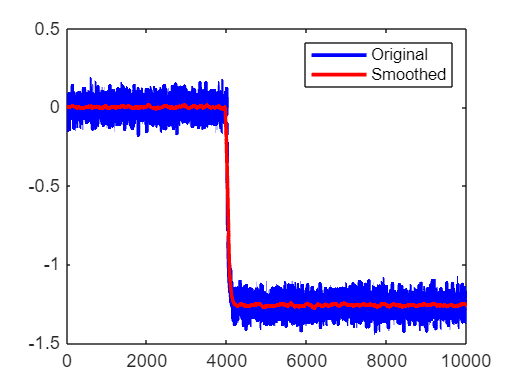

% Plot the smoothed data
plot(tspan, norm_y1, '-b', 'LineWidth',2);
hold on;
plot(tspan, smoothed_y, '-r', 'LineWidth', 2);  % Smoothed line
legend('Original', 'Smoothed');
hold off;

 %Data Smoothened.
 %Now, For Different time window, I am to find out the max peak reached.

% FOPTD model definition (Kp * (1 - exp(-(t-theta)/tau)) * (t >= theta))
FOPTD_model = @(t, params) D_values_norm(8000) *params(1)*(1 - exp(-(t - params(3))/params(2))) .* (t >= t_change);
%Editing this thing.


% Ensure that smoothed_y and tspan are column vectors for consistency
tspan = tspan(:);  % Convert tspan to column vector
smoothed_y = smoothed_y(:);  % Convert smoothed_y to column vector

% Define the error function (difference between FOPTD model and smoothed_y data)
error_function = @(params) sum((smoothed_y - FOPTD_model(tspan, params)).^2);

% Initial guess for parameters [Kp, tau, theta]
initial_guess = [1, 10, 2];

% Optimization options to increase the number of function evaluations
options = optimset('MaxFunEvals', 10000, 'MaxIter', 10000);

% Use fminsearch to find the best-fitting parameters
FOPTD_params = fminsearch(error_function, initial_guess, options);

% Extract fitted FOPTD parameters
Kp_fitted = FOPTD_params(1);
tau_fitted = FOPTD_params(2);
theta_fitted = FOPTD_params(3);

% Display the fitted parameters
fprintf('Fitted FOPTD parameters:\n');

Fitted FOPTD parameters:


fprintf('Kp = %.4f\n', Kp_fitted);

Kp = -61.9342


fprintf('Tau = %.4f\n', tau_fitted);

Tau = 175.3732


fprintf('Theta = %.4f\n', theta_fitted);

Theta = 30.7942


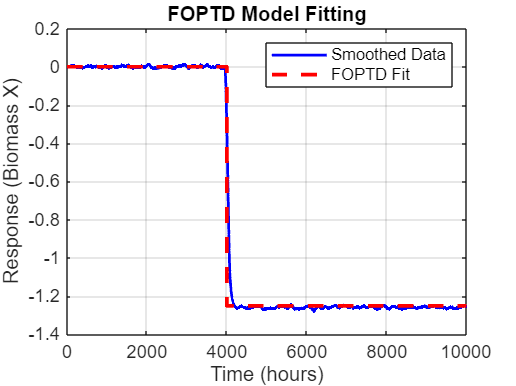


% Simulate the FOPTD model using the fitted parameters
y_foptd = FOPTD_model(tspan, FOPTD_params);

% Plot the original smoothed data and the FOPTD model fit
figure;
plot(tspan, smoothed_y, '-b', 'LineWidth', 1.5); hold on;
plot(tspan, y_foptd, '--r', 'LineWidth', 2);
legend('Smoothed Data', 'FOPTD Fit');
xlabel('Time (hours)');
ylabel('Response (Biomass X)');
title('FOPTD Model Fitting');
grid on;



%Got the FOPTD model; Now, going for validation;

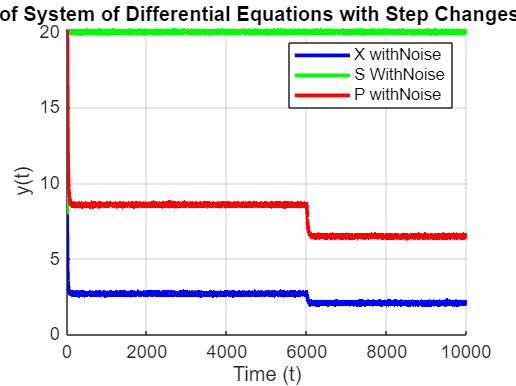

%recreating the above plots, for a different step change; I think it should
%work.

t_change = 6000;
D = @(t) 0.202 + 0.0102*(t>= t_change); % + 0.0302*(t>4000 & t<=6000) + 0.0101*(t>6000 &t<8000); 
% Define the system of differential equations with step changes
dydt_step_change = @(t, y) [-D(t)* y(1) + mu(y(2), y(3))*y(1);
                D(t)*(S_f-y(2))*(1/Y_x_s)*mu(y(2), y(3))*y(1);
               -D(t)*y(3) + (alpha*mu(y(2), y(3)) + beta)*y(1)];
%Here, I have commented out another method in order to depict the step
%change variables. I would incorporate that later, if need be.


% Solve the system with step changes
[t_step, y_step] = ode45(dydt_step_change, tspan, y0);

% Add noise to the step-changed solution (random noise)
noise_amplitude = 0.05;  % Adjust this value for noise intensity
y_step_noisy = y_step+ noise_amplitude * randn(size(y_step));
%Commented out the noise.



% Plot the solutions

figure;
hold on;


% Plot the noisy step-changed solution (solid lines with noise)
plot(t_step, y_step_noisy(:, 1), 'b-', 'LineWidth', 2, 'DisplayName', 'X withNoise');
plot(t_step, y_step_noisy(:, 2), 'g-', 'LineWidth', 2, 'DisplayName', 'S WithNoise');
plot(t_step, y_step_noisy(:, 3), 'r-', 'LineWidth', 2, 'DisplayName', 'P withNoise');

% Add labels, title, and legend
xlabel('Time (t)');
ylabel('y(t)');
title('Solution of System of Differential Equations with Step Changes and Noise');
legend('show');
grid on;
hold off;

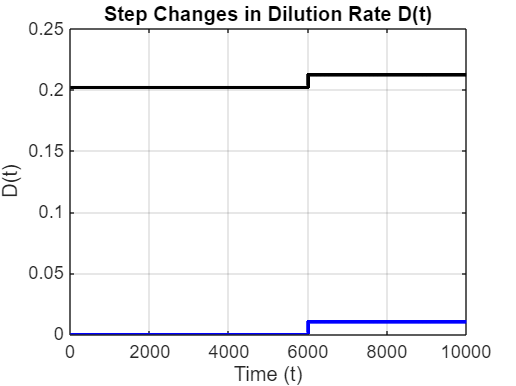



%Plotting the D values:

t_D = linspace(0, 10000, 10000);  % Time span for D(t)
D_values = D(t_D);  % Evaluate D(t)
D_values_norm = D_values - D(0);
figure; % Create a new figure
plot(t_D, D_values, 'k-', 'LineWidth', 2); % Plot D(t)
hold on;
plot(t_D, D_values_norm, 'b-', 'LineWidth', 2);
xlabel('Time (t)');
ylabel('D(t)');
title('Step Changes in Dilution Rate D(t)');
grid on;

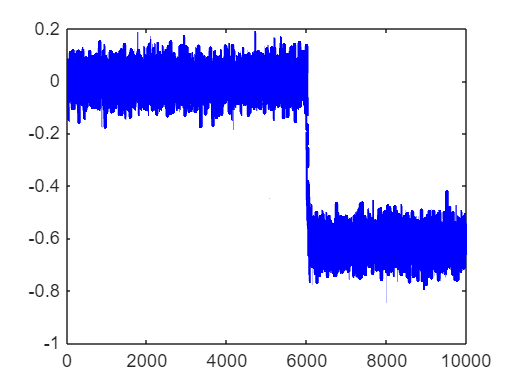


figure;
plot(t_step, y_step_noisy(:, 1)-y_original(:, 1), 'b-', 'LineWidth', 2, 'DisplayName', 'X withNoise');

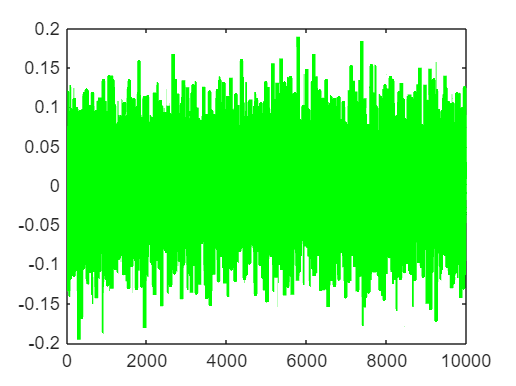

plot(t_step, y_step_noisy(:, 2)-y_original(:, 2), 'g-', 'LineWidth', 2, 'DisplayName', 'S WithNoise');

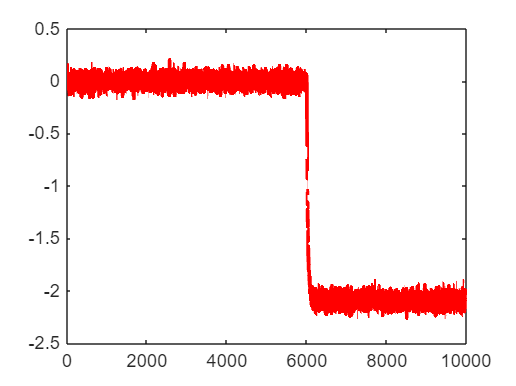

plot(t_step, y_step_noisy(:, 3)-y_original(:, 3), 'r-', 'LineWidth', 2, 'DisplayName', 'P withNoise');

norm_y1 = y_step_noisy(:, 1)-y_original(:, 1);
norm_y2 = y_step_noisy(:, 2)-y_original(:, 2);
norm_y3 = y_step_noisy(:, 3)-y_original(:, 3);

%Everything got normalized. Now, smoothing the curve;


%Using basic calculations; 
smoothed_y = smoothdata(norm_y1, 'movmean', 100)

smoothed_y =    -0.0074
   -0.0075
   -0.0075
   -0.0080
   -0.0086
   -0.0085
   -0.0084
   -0.0087
   -0.0080
   -0.0087


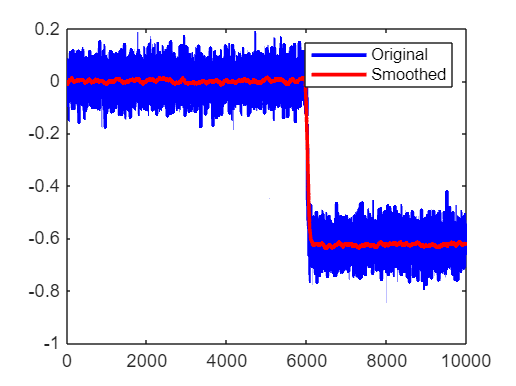

% Plot the smoothed data
plot(tspan, norm_y1, '-b', 'LineWidth',2);
hold on;
plot(tspan, smoothed_y, '-r', 'LineWidth', 2);  % Smoothed line
legend('Original', 'Smoothed');
hold off;

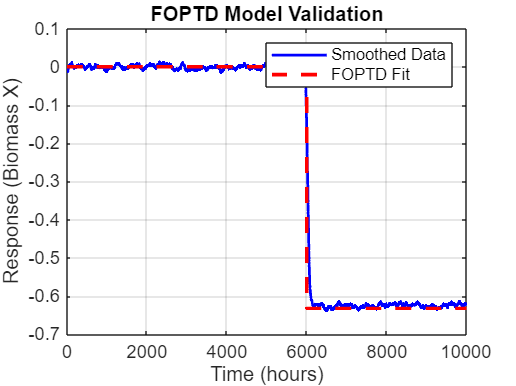

 %Data Smoothened.
 %Now, For Different time window, I am to find out the max peak reached.

 %I have the kp;
%Kp should remain same, what should change is the A value.
FOPTD_model = @(t, params) D_values_norm(8000) *params(1)*(1 - exp(-(t - params(3))/params(2))) .* (t >= t_change);
y_foptd = FOPTD_model(tspan, FOPTD_params);

% Plot the original smoothed data and the FOPTD model fit
figure;
plot(tspan, smoothed_y, '-b', 'LineWidth', 1.5); hold on;
plot(tspan, y_foptd, '--r', 'LineWidth', 2);
legend('Smoothed Data', 'FOPTD Fit');
xlabel('Time (hours)');
ylabel('Response (Biomass X)');
title('FOPTD Model Validation');
grid on;